# MPC HW5

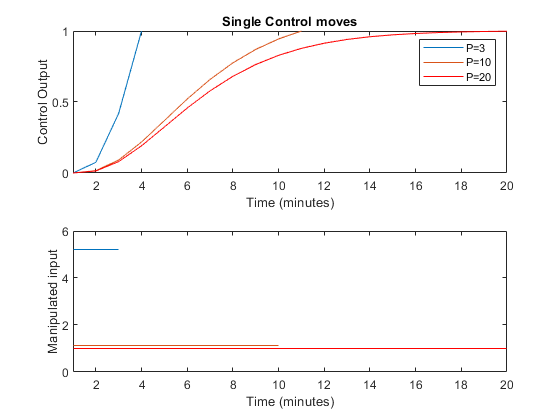

% Author Lucky Yerimah
% Date 20th Febuary 2020

%   Define variables
%   Create discrete state space 
%   Extract the state space data to [Az,Bz,Cz,Dz]
%   Compute f as a summation
%   use f to calculate the single control moves for different values of P
%   horizon
%   create a cell of the control moves with name Controls
%   use a double for loop to compute the output response using different time intervals which depend on P
%   pass each set of outputs to y_out cell
%   plot each y_out and corresponding control moves

A = [-1, 0, 0; 1, -1, 0; 0, 1, -1];
B = [1;0;0];
C = [0,0,1];
D = 0;
sys = ss(A,B,C,D); % converting matrices to state space 
Gz = c2d(sys,0.5); % Discrete-time transfer function
x0 = [0;0;0]; % initial conditions for the states
[Az,Bz,Cz,Dz] = ssdata(Gz);
tbeng = 0;
deltaT = 0.5;
r = 1;
P = [3,10,20];
f = [0;0;0];

for i = 1:3      
for j = 1:P(i)
    f(i,1) = f(i,1) + Cz*Az^(P(i)-j)*Bz;
  
end
end 

u_single3(1:3,1) = (r-(C*(Az^P(1))*x0))/f(1,1);
u_single10(1:10,1) = (r-(C*(Az^P(2))*x0))/f(2,1);
u_single20(1:20,1) = (r-(C*(Az^P(3))*x0))/f(3,1);
Controls = {u_single3,u_single10,u_single20};
y_out = cell(3,1);
for i = 1:3
    
   tend = P(i)/2;
time = tbeng:deltaT:tend; 
y = zeros(length(time)); % create a vector to hold y values

for k = 1:length(time)-1
    [~,xnew] = ode45(@(t,x) plantmodel(t,x,Controls{i}(k,1)),[time(k) time(k+1)], x0); % ODE45 function
y(k+1) = xnew(end,end); % output as last value of xnew
x0= xnew(end,:)'; % assigning states variables as input for next iteration
end
y_out{i} = y(:,1); % pass y values to y_out cell
x0 = [0;0;0]; % reinitialize conditions for the states
end


figure(1)
subplot(2,1,1)
plot(y_out{1}(:,1))
hold on
plot(y_out{2}(:,1))
plot(y_out{3}(:,1),'r')
hold off
xlabel('Time (minutes)')
ylabel('Control Output')
legend('P=3','P=10','P=20')
title("Single Control moves")
xlim([1 20])

subplot(2,1,2)
stairs(u_single3)
hold on
stairs(u_single10)
stairs(u_single20,'r')
hold off
xlabel('Time (minutes)')
ylabel('Manipulated input')
ylim([0 6])
xlim([1 20])

## Problem two

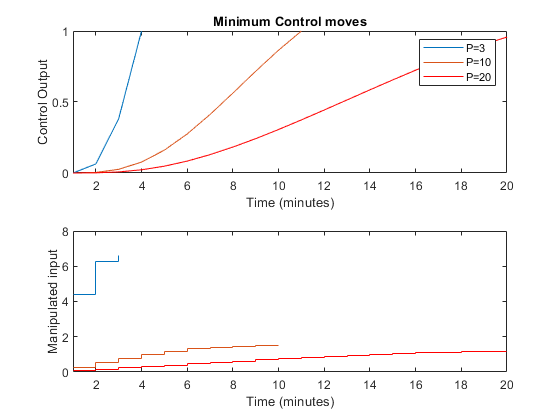

% using this equation Ax = b
%   Define variables
%   Compute F as a summation and pass each value to A_matrix
%   Use A_matrix for the different values of P
%   calculate b and compute x as sum of squares x = pinv(A)*b as the change
%   in u (i.e delta_u)
%   use x to compute the control moves using the cummulative sum function
%   create a cell of the control moves with name New_Controls
%   use a double for loop to compute the output response using different time intervals which depend on P
%   pass each set of outputs to y_out2 cell
%   plot each y_out2 and corresponding control moves

P = 20;
F = 0;
u_k_1 = 0; % u(k-1)
x0 = [0;0;0]; % initial conditions for the states

for j=1:P
    F = F + Cz*Az^(j-1)*Bz;
    A_matrix(P+1-j) = F; 
end
A3 = A_matrix(end-2:end);
A10 = A_matrix(end-9:end);
A20 = A_matrix;

b3 = r - Cz*(Az^3)*x0;
b10 = r - Cz*(Az^10)*x0;
b20 = r - Cz*(Az^20)*x0;

delta_u3 = pinv(A3)*b3;
delta_u10 = pinv(A10)*b10;
delta_u20 = pinv(A20)*b20;

u_min3 = cumsum(delta_u3);
u_min10 = cumsum(delta_u10);
u_min20 = cumsum(delta_u20);
P = [3,10,20];
New_Controls = {u_min3,u_min10,u_min20};
y_out2 = cell(3,1);

for i = 1:3
    
   tend = P(i)/2;
time = tbeng:deltaT:tend; 
y = zeros(length(time));

for k = 1:length(time)-1
    [~,xnew] = ode45(@(t,x) plantmodel(t,x,New_Controls{i}(k,1)),[time(k) time(k+1)], x0); % ODE45 function
y(k+1) = xnew(end,end); % output as last value of xnew
x0= xnew(end,:)'; % assigning states variables as input for next iteration
end
y_out2{i} = y(:,1); % pass y values to y_out cell
x0 = [0;0;0]; % reinitialize conditions for the states
end

figure(2)
subplot(2,1,1)
plot(y_out2{1}(:,1))
hold on
plot(y_out2{2}(:,1))
plot(y_out2{3}(:,1),'r')
hold off
xlabel('Time (minutes)')
ylabel('Control Output')
legend('P=3','P=10','P=20')
title("Minimum Control moves")
xlim([1 20])

subplot(2,1,2)
stairs(u_min3(:,1))
hold on
stairs(u_min10(:,1))
stairs(u_min20(:,1),'r')
hold off
xlabel('Time (minutes)')
ylabel('Manipulated input')
xlim([1 20])

## Problem Three

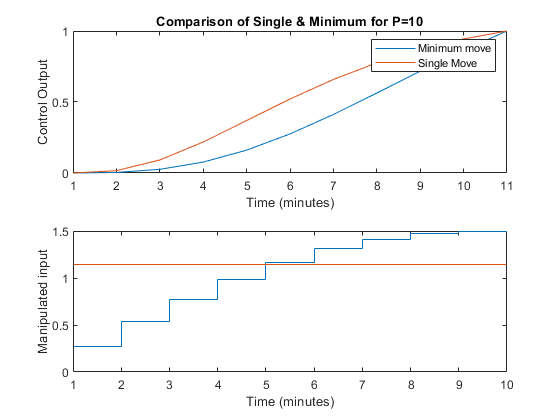

% By observing figure i and 2, it is obvious that both control moves
% brought the output to the desied setpoint value at the same time.
% ALthough, the sum of squares control moves includes gradual increase in
% the input. Especially for the prediction horizon of 3. Also, the sum of
% squares required less number of moves to attain desired setpoint.

figure(3)
subplot(2,1,1)
plot(y_out2{2}(:,1))
hold on
plot(y_out{2}(:,1))
hold off
xlabel('Time (minutes)')
ylabel('Control Output')
legend('Minimum move','Single Move')
title("Comparison of Single & Minimum for P=10")

subplot(2,1,2)
stairs(u_min10(:,1))
hold on
stairs(u_single10)
hold off
xlabel('Time (minutes)')
ylabel('Manipulated input')

## Problem Four

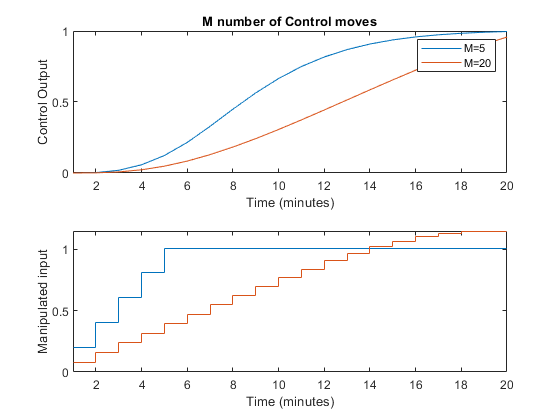

%   Define variables
%   Compute F as a summation and pass each value to A_matrix
%   Pass the first 5 values of A_matrix to A_M5 to for the 5 control moves
%   use both A_matrix to compute the delta_u
%   calculate b and compute x as sum of squares x = pinv(A)*b as the change
%   in u (i.e delta_u)
%   use x to compute the control moves using the cummulative sum function
%   create a cell of the control moves with name New_Controls
%   use a double for loop to compute the output response using different time intervals which depend on P
%   pass each set of outputs to y_out3 cell
%   plot each y_out3 and corresponding control moves

P = 20;
F = 0;
r = 1;
u_k_1 = 0; % u(k-1)
x0 = [0;0;0]; % initial conditions for the states
for j=1:P
    F = F + Cz*Az^(j-1)*Bz;
    A_matrix(P+1-j) = F; 
end
A20 = A_matrix;
A_M5 = A_matrix(1,1:5);
b20 = r - Cz*(Az^20)*x0;
delta_u20 = pinv(A20)*b20;
delta_u5 = pinv(A_M5)*b20;
M_moves5(1:5,1) = delta_u5;
M_moves5(6:20,1) = zeros(15,1);
M_moves20 = delta_u20;
u_M_Moves5 = cumsum(M_moves5);
u_M_Moves20 = cumsum(delta_u20);
M_Moves_Controls = {u_M_Moves5,u_M_Moves20};
y_out3 = cell(2,1);
tend = P/2;
time = tbeng:deltaT:tend; 
y = zeros(length(time));

for i = 1:2    
for k = 1:length(time)-1
    [~,xnew] = ode45(@(t,x) plantmodel(t,x,M_Moves_Controls{i}(k,1)),[time(k) time(k+1)], x0); % ODE45 function
y(k+1) = xnew(end,end); % output as last value of xnew
x0= xnew(end,:)'; % assigning states variables as input for next iteration
end
y_out3{i} = y(:,1);
x0 = [0;0;0]; % reinitialize conditions for the states
end

figure(4)
subplot(2,1,1)
plot(y_out3{1}(:,1))
hold on
plot(y_out3{2}(:,1))
hold off
xlabel('Time (minutes)')
ylabel('Control Output')
legend('M=5','M=20')
title("M number of Control moves")
xlim([1 20])

subplot(2,1,2)
stairs(u_M_Moves5(:,1))
hold on
stairs(u_M_Moves20(:,1))
hold off
xlabel('Time (minutes)')
ylabel('Manipulated input')
xlim([1 20])

## Continuous Plant

function xdot = plantmodel(t,x,u)
% State space equations 
xdot(1) = -x(1) + u;
xdot(2) = x(1) - x(2);
xdot(3) = x(2) - x(3);

xdot = xdot'; % converting the ODEs to column vector
end
